% Load the dataset
data = readtable('C:\Users\OMBATI\Documents\HW3data.csv');
returns = data{:, 2:end}; % Extract returns data

% Display the first 10 rows and last 10 rows of the data
fprintf('First 10 Rows of Dataset:\n');

First 10 Rows of Dataset:


disp(data(1:10, :));

       Date        Cnsmr      Manuf      HiTec      Hlth       Other 
    __________    _______    _______    _______    _______    _______

    1.9261e+05     0.0543     0.0273     0.0183     0.0177     0.0213
    1.9261e+05     0.0276     0.0233     0.0241     0.0425     0.0435
    1.9261e+05     0.0216    -0.0044     0.0106     0.0069     0.0029
    1.9261e+05     -0.039    -0.0242    -0.0226    -0.0057    -0.0284
    1.9261e+05      0.037      0.025     0.0307     0.0542     0.0211
    1.9261e+05     0.0362     0.0276     0.0103     0.0011     0.0347
     1.927e+05    -0.0119     0.0015     0.0046     0.0505      0.015
     1.927e+05     0.0528       0.04     0.0419     0.0171     0.0505
     1.927e+05     0.0164    -0.0143     0.0365     0.0101     0.0122
     1.927e+05     0.0352

fprintf('Last 10 Rows of Dataset:\n');

Last 10 Rows of Dataset:


disp(data(end-9:end, :));

       Date        Cnsmr      Manuf      HiTec      Hlth       Other 
    __________    _______    _______    _______    _______    _______

    2.0221e+05    -0.0762    -0.1095    -0.1161    -0.0191    -0.0791
    2.0221e+05     0.0386     0.1346     0.0532     0.0884      0.116
    2.0221e+05     0.0246     0.0624     0.0499     0.0546       0.06
    2.0221e+05    -0.0936    -0.0257    -0.0777    -0.0173    -0.0527
     2.023e+05     0.0908     0.0365      0.101    -0.0102     0.0708
     2.023e+05    -0.0199     -0.039    -0.0075     -0.043     -0.026
     2.023e+05     0.0273     0.0087     0.0952     0.0253     -0.046
     2.023e+05    -0.0011     0.0071     0.0038     0.0408     0.0206
    2.0231e+05     0.0048    -0.0673     0.0695    -0.0377    -0.0273
    2.0231e+05     0.0896

% Part (1a): (a) Compute the annualized expected returns and covariance matrix. (Hint: Estimate the expected returns and covariance matrix of monthly returns first, then multiply them by 12.) Note: this is the same question as 3(a) on Problem Set 2.
nMonths = size(returns, 1);
nAssets = size(returns, 2);
annualReturns = mean(returns) * 12;
covarianceMatrix = cov(returns) * 12;

% Display results of Part (1a)
fprintf('Part (1a) - Annualized Expected Returns:\n');

Part (1a) - Annualized Expected Returns:


disp(annualReturns);

    0.1211    0.1152    0.1189    0.1291    0.1093



fprintf('Part (1a) - Covariance Matrix:\n');

Part (1a) - Covariance Matrix:


disp(covarianceMatrix);

    0.0335    0.0303    0.0289    0.0271    0.0354
    0.0303    0.0365    0.0296    0.0272    0.0378
    0.0289    0.0296    0.0375    0.0261    0.0341
    0.0271    0.0272    0.0261    0.0366    0.0312
    0.0354    0.0378    0.0341    0.0312    0.0491



% Part (1b): Find MVE portfolio weights and Sharpe Ratio
riskFreeRate = 0.03; 
rfPortfolioWeights = (annualReturns - riskFreeRate) ./ (covarianceMatrix * ones(nAssets, 1));
rfPortfolioWeights = rfPortfolioWeights / sum(rfPortfolioWeights); 
rfPortfolioReturn = rfPortfolioWeights' * annualReturns';
rfPortfolioRisk = sqrt(rfPortfolioWeights' * covarianceMatrix * rfPortfolioWeights);
rfSharpeRatio = (rfPortfolioReturn - riskFreeRate) / rfPortfolioRisk;

% Display results of Part (1b)
fprintf('Part (1b) - Risk-Free Portfolio Weights:\n');

Part (1b) - Risk-Free Portfolio Weights:


disp(rfPortfolioWeights);

    0.2070
    0.1991
    0.2056
    0.2170
    0.1713



fprintf('Part (1b) - Risk-Free Portfolio Return: %.4f\n', rfPortfolioReturn);

Part (1b) - Risk-Free Portfolio Return: 0.1192


fprintf('Part (1b) - Risk-Free Portfolio Risk: %.4f\n', rfPortfolioRisk);

Part (1b) - Risk-Free Portfolio Risk: 0.1787


fprintf('Part (1b) - Risk-Free Portfolio Sharpe Ratio: %.4f\n', rfSharpeRatio);

Part (1b) - Risk-Free Portfolio Sharpe Ratio: 0.4991


% Part (c): You have been hired to manage the portfolio of a mean-variance investor with a coefficient of risk aversion γ = 3. You have decided to invest in these 5 industry portfolios and the risk free asset. Find the optimal portfolio weights for the investors and compute the Sharpe Ratio of the portfolio.
gamma = 3; 
Aeq = ones(1, nAssets);
beq = 1;
lb = zeros(nAssets, 1); 
ub = ones(nAssets, 1);
mvPortfolioWeights = quadprog(gamma * covarianceMatrix, [], [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


mvPortfolioReturn = mvPortfolioWeights' * annualReturns';
mvPortfolioRisk = sqrt(mvPortfolioWeights' * covarianceMatrix * mvPortfolioWeights);
mvSharpeRatio = (mvPortfolioReturn - riskFreeRate) / mvPortfolioRisk;

% Display results of Part (1c)
fprintf('Part (1c) - Mean-Variance Efficient Portfolio Weights:\n');

Part (1c) - Mean-Variance Efficient Portfolio Weights:


disp(mvPortfolioWeights);

    0.3203
    0.1351
    0.2175
    0.3271
    0.0000



fprintf('Part (1c) - Mean-Variance Efficient Portfolio Return: %.4f\n', mvPortfolioReturn);

Part (1c) - Mean-Variance Efficient Portfolio Return: 0.1225


fprintf('Part (1c) - Mean-Variance Efficient Portfolio Risk: %.4f\n', mvPortfolioRisk);

Part (1c) - Mean-Variance Efficient Portfolio Risk: 0.1731


fprintf('Part (1c) - Mean-Variance Efficient Portfolio Sharpe Ratio: %.4f\n', mvSharpeRatio);

Part (1c) - Mean-Variance Efficient Portfolio Sharpe Ratio: 0.5340


% Part (1d): How does the Sharpe Ratio in part (b) compare to the one in part (c)? Explain.
fprintf('Part (1d) - Sharpe Ratio for Risk-Free Portfolio (b): %.4f\n', rfSharpeRatio);

Part (1d) - Sharpe Ratio for Risk-Free Portfolio (b): 0.4991


fprintf('Part (1d) - Sharpe Ratio for Mean-Variance Efficient Portfolio (c): %.4f\n', mvSharpeRatio);

Part (1d) - Sharpe Ratio for Mean-Variance Efficient Portfolio (c): 0.5340


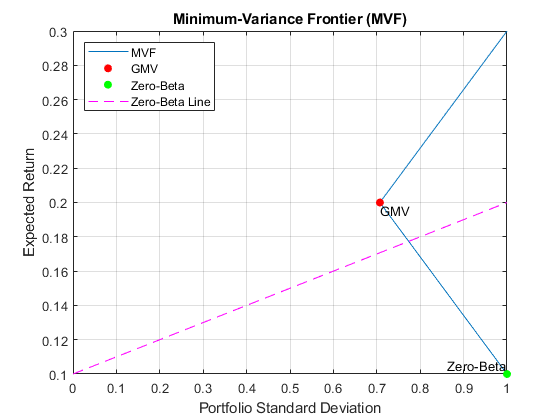

% Part 2: The Geometry of the MVF
expectedReturns = [0.10; 0.20; 0.30];
covMatrix = [1 0 0; 0 1 0; 0 0 1];

% (a) Calculate portfolio standard deviation as a function of expected return
nPoints = length(expectedReturns);
portfolios = linspace(0, 1, nPoints);
portStdDeviations = sqrt(portfolios.^2 * (covMatrix(1, 1)) + (1 - portfolios).^2 * (covMatrix(2, 2)) + ...
    2 * portfolios .* (1 - portfolios) * (covMatrix(1, 2)));

% (b) Plot the MVF
figure;
plot(portStdDeviations, expectedReturns);
xlabel('Portfolio Standard Deviation');
ylabel('Expected Return');
title('Minimum-Variance Frontier (MVF)');
grid on;


% (2c) Find the global minimum-variance portfolio xGM V .
[~, minVarIdx] = min(portStdDeviations);
xGMV = portfolios(minVarIdx);
rGMV = expectedReturns(minVarIdx);

% (2d) Label the minimum-variance portfolio p′ with E[rp′ ] = 25% on the MVF you draw in part (b).
hold on;
scatter(portStdDeviations(minVarIdx), expectedReturns(minVarIdx), 'r', 'filled');
text(portStdDeviations(minVarIdx), expectedReturns(minVarIdx), 'GMV', 'VerticalAlignment', 'top');

% (2e) Find a portfolio p′′ on the MVF which is uncorrelated with p′ and label it on the plot you draw in part (b). p′′ is called the zero-beta portfolio for p′.
zeroBetaPortfolio = [1; -covMatrix(1, 2) / covMatrix(2, 2); 0];
zeroBetaPortfolio = zeroBetaPortfolio / sum(zeroBetaPortfolio);
zeroBetaReturn = zeroBetaPortfolio' * expectedReturns;
zeroBetaStdDev = sqrt(zeroBetaPortfolio' * covMatrix * zeroBetaPortfolio);

% Label zero-beta portfolio on the plot
scatter(zeroBetaStdDev, zeroBetaReturn, 'g', 'filled');
text(zeroBetaStdDev, zeroBetaReturn, 'Zero-Beta', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');

% (2f)  Now draw a straight line that passes through (0, rp′′ ) and (σp′ , rp′ ). What do you find? Hint: you should conclude that you have found a geometric method to determine the expected return of the zero-beta portfolio for almost any portfolio on the MVF.
line([0, zeroBetaStdDev], [zeroBetaReturn, expectedReturns(minVarIdx)], 'Color', 'm', 'LineStyle', '--');
legend('MVF', 'GMV', 'Zero-Beta', 'Zero-Beta Line', 'Location', 'northwest');

% Part 3: Implementing MPT with Portfolio Constraints

% Given data
riskFreeRate = 0.01; % Risk-free rate is 1%
assetReturns = [0.08; 0.037; 0.06];
assetVolatility = [0.19; 0.25; 0.15];
correlationMatrix = [1 0.5 0.8; 0.5 1 0.2; 0.8 0.2 1];
gamma = 2; % Coefficient of risk aversion

% Part (3a): Compute the MVE portfolio weights and the Sharpe Ratio in the absence of portfolio constraints. Verify that you get the same numbers as we got in the Topic 2 notes.
Aeq = ones(1, 3);
beq = 1;
lb = zeros(3, 1); 
ub = [];
mvePortfolioWeights = quadprog(gamma * correlationMatrix, [], [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


mvePortfolioReturn = mvePortfolioWeights' * assetReturns;
mvePortfolioRisk = sqrt(mvePortfolioWeights' * correlationMatrix * mvePortfolioWeights);
mveSharpeRatio = (mvePortfolioReturn - riskFreeRate) / mvePortfolioRisk;

% Display results of Part (3a)
fprintf('Part (3a) - MVE Portfolio Weights:\n');

Part (3a) - MVE Portfolio Weights:


disp(mvePortfolioWeights);

    0.0000
    0.5000
    0.5000



fprintf('Part (3a) - MVE Portfolio Return: %.4f\n', mvePortfolioReturn);

Part (3a) - MVE Portfolio Return: 0.0485


fprintf('Part (3a) - MVE Portfolio Risk: %.4f\n', mvePortfolioRisk);

Part (3a) - MVE Portfolio Risk: 0.7746


fprintf('Part (3a) - MVE Portfolio Sharpe Ratio: %.4f\n', mveSharpeRatio);

Part (3a) - MVE Portfolio Sharpe Ratio: 0.0497


% Part (3b):  Now impose a no short-sales constraint (i.e., the portfolio weight in each asset must be non-negative). Based on your answer to part (i), for which asset will the constraint bind? Hint: you do not need to use numerical methods in Excel or Matlab to solve this or any other part of this question. Just use your common sense!
bindingAsset = find(mvePortfolioWeights == max(mvePortfolioWeights));

% Display result of Part (3b)
fprintf('Part (3b) - Asset with Binding Constraint: Asset %d\n', bindingAsset);

Part (3b) - Asset with Binding Constraint: Asset 2


% Part (3c):  Now impose a no short-sales constraint (i.e., the portfolio weight in each asset must be non-negative). Based on your answer to part (i), for which asset will the constraint bind? Hint: you do not need to use numerical methods in Excel or Matlab to solve this or any other part of this question. Just use your common sense!
lb(bindingAsset) = 0; 
ub = ones(3, 1);
constrainedMVEPortfolioWeights = quadprog(gamma * correlationMatrix, [], [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


constrainedMVEPortfolioReturn = constrainedMVEPortfolioWeights' * assetReturns;
constrainedMVEPortfolioRisk = sqrt(constrainedMVEPortfolioWeights' * correlationMatrix * constrainedMVEPortfolioWeights);
constrainedMVESharpeRatio = (constrainedMVEPortfolioReturn - riskFreeRate) / constrainedMVEPortfolioRisk;

% Display results of Part (3c)
fprintf('Part (3c) - Constrained MVE Portfolio Weights:\n');

Part (3c) - Constrained MVE Portfolio Weights:


disp(constrainedMVEPortfolioWeights);

    0.0000
    0.5000
    0.5000



fprintf('Part (3c) - Constrained MVE Portfolio Return: %.4f\n', constrainedMVEPortfolioReturn);

Part (3c) - Constrained MVE Portfolio Return: 0.0485


fprintf('Part (3c) - Constrained MVE Portfolio Risk: %.4f\n', constrainedMVEPortfolioRisk);

Part (3c) - Constrained MVE Portfolio Risk: 0.7746


fprintf('Part (3c) - Constrained MVE Portfolio Sharpe Ratio: %.4f\n', constrainedMVESharpeRatio);

Part (3c) - Constrained MVE Portfolio Sharpe Ratio: 0.0497


% Part 3, Question (d): Calculate optimal portfolio weights for a mean-variance investor with γ = 2
gamma = 2; 

% constraints
Aeq = ones(1, 3);
beq = 1;
lb = zeros(3, 1); 
ub = ones(3, 1);

% optimal portfolio weights
optimalPortfolioWeights = quadprog(gamma * correlationMatrix, [], [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% portfolio statistics
optimalPortfolioReturn = optimalPortfolioWeights' * assetReturns;
optimalPortfolioRisk = sqrt(optimalPortfolioWeights' * correlationMatrix * optimalPortfolioWeights);
optimalPortfolioSharpeRatio = (optimalPortfolioReturn - riskFreeRate) / optimalPortfolioRisk;

% Display results
fprintf('Part (3d) - Optimal Portfolio Weights:\n');

Part (3d) - Optimal Portfolio Weights:


disp(optimalPortfolioWeights);

    0.0000
    0.5000
    0.5000



fprintf('Part (3d) - Optimal Portfolio Return: %.4f\n', optimalPortfolioReturn);

Part (3d) - Optimal Portfolio Return: 0.0485


fprintf('Part (3d) - Optimal Portfolio Risk: %.4f\n', optimalPortfolioRisk);

Part (3d) - Optimal Portfolio Risk: 0.7746


fprintf('Part (3d) - Optimal Portfolio Sharpe Ratio: %.4f\n', optimalPortfolioSharpeRatio);

Part (3d) - Optimal Portfolio Sharpe Ratio: 0.0497
